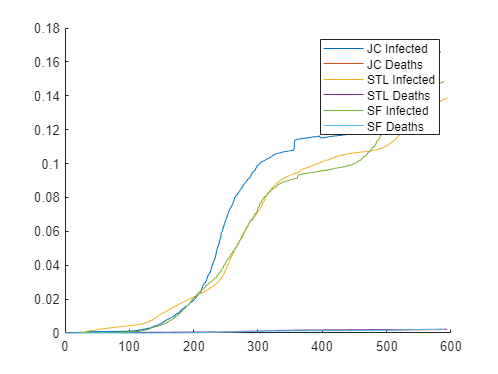

% Here is an example that reads in infection and fatalities from STL City
% and loads them into a new matrix covidstlcity_full
% In addition to this, you have other matrices for the other two regions in question
% DEBUG
base_data = load("COVIDdata.mat");

coviddata = load("COVIDdata.mat");
casedata = coviddata.COVID_MO;
pops = containers.Map({'Jefferson City','St. Louis','Springfield'},[150198,2805473,475220]);
start = 200;
t = 200; % TO SPECIFY
jc_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==1,setdiff(1:4,2));
jc = table2array(jc_data(:,2:3))./pops('Jefferson City');
stl_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==2,setdiff(1:4,2));
stl = table2array(stl_data(:,2:3));
stl = stl./pops('St. Louis');
sf_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==3,setdiff(1:4,2));
sf = table2array(sf_data(:,2:3))./pops('Springfield');
figure;
hold on
plot(jc)
plot(stl)
plot(sf)
legend('JC Infected', 'JC Deaths', 'STL Infected', 'STL Deaths', 'SF Infected', 'SF Deaths')
hold off

coviddata = jc(start:start+t-1,:);


% The following line creates an 'anonymous' function that will return the cost (i.e., the model fitting error) given a set
% of parameters.  There are some technical reasons for setting this up in this way.
% Feel free to peruse the MATLAB help at
% https://www.mathworks.com/help/optim/ug/fmincon.html
% and see the sectiono on 'passing extra arguments'
% Basically, 'sirafun' is being set as the function siroutput (which you
% will be designing) but with t and coviddata specified.
sirafun= @(x)sliroutput(x,t,coviddata);

## set up rate and initial condition constraints

Set A and b to impose a parameter inequality constraint of the form A*x < b Note that this is imposed element-wise If you don't want such a constraint, keep these matrices empty.

A = [];
b = [];

## set up some fixed constraints

Set Af and bf to impose a parameter constraint of the form Af*x = bf Hint: For example, the sum of the initial conditions should be constrained If you don't want such a constraint, keep these matrices empty.

Af = [];
bf = [];

## set up upper and lower bound constraints

Set upper and lower bounds on the parameters lb < x < ub here, the inequality is imposed element-wise If you don't want such a constraint, keep these matrices empty.

ub = ones(1,9)';
lb = zeros(1,9)';

% Specify some initial parameters for the optimizer to start from
% Inf; Fat; Rec; Vac; Lock; Exit; ILock; Susc; Lock; Inf; Rec; Fat
x0 = [0.02 0.01 0.1 0.1 0.98 0 0.02 0 0]

x0 =     0.0200    0.0100    0.1000    0.1000    0.9800         0    0.0200         0         0



% This is the key line that tries to opimize your model parameters in order to
% fit the data
% note tath you 
options = optimoptions("fmincon","MaxFunctionEvaluations",50000);
x = fmincon(sirafun,x0,A,b,Af,bf,lb,ub,[],options);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


k_infections = x(1)

k_infections = 0.0038

k_fatality = x(2)

k_fatality = 6.0721e-05

k_recover = x(3)

k_recover = 0.0016

k_vac = x(4)

k_vac = 0.0062


% set up initial conditions
ic_susc = x(5);
ic_lock = x(6);
ic_inf = x(7);
ic_rec = x(8);
ic_fatality = x(9);

% Set up SIRD within-population transmission matrix
A = [1-jinf-jvac 0 0 0 0 stj 0 0 0 0 ssj 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
    jinf 0 1-jrec-jfat 0 0 0 0 itj 0 0 0 0 isj 0 0;
    jvac 0 jrec 1 0 0 0 0 rtj 0 0 0 0 rsj 0;
    0 0 jfat 0 1 0 0 0 0 0 0 0 0 0 0;
    sjt 0 0 0 0 1-tinf-tvac 0 0 0 0 sst 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
    0 0 ijt 0 0 tinf 0 1-trec-tfat 0 0 0 0 ist 0 0;
    0 0 0 rjt 0 tvac 0 trec 1 0 0 0 0 rst 0;
    0 0 0 0 0 0 0 tfat 0 1 0 0 0 0 0;
    sjs 0 0 0 0 sts 0 0 0 0 1-sinf-svac 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
    0 0 ijs 0 0 0 0 its 0 0 sinf 0 1-srec-sfat 0 0;
    0 0 0 rjs 0 0 0 0 rts 0 svac 0 srec 1 0;
    0 0 0 0 0 0 0 0 0 0 0 0 sfat 0 1];
B = zeros(15,1);

% Set up the vector of initial conditions
x0 = [ic_susc, ic_lock, ic_inf, ic_rec, ic_fatality];

sys_sir_base = ss(A,B,eye(5),zeros(5,1),1);
y = lsim(sys_sir_base,zeros(t,1),linspace(0,t-1,t),x0)

y =     0.4184    0.5004    0.0071    0.5004    0.0005
    0.4142         0    0.0087    0.5030    0.0005
    0.4100         0    0.0103    0.5056    0.0005
    0.4059         0    0.0118    0.5082    0.0005
    0.4018         0    0.0134    0.5108    0.0005
    0.3978         0    0.0149    0.5133    0.0005
    0.3938         0    0.0164    0.5158    0.0005
    0.3898         0    0.0179    0.5183    0.0005
    0.3859         0    0.0193    0.5207    0.0005
    0.3820         0    0.0208    0.5232    0.0005


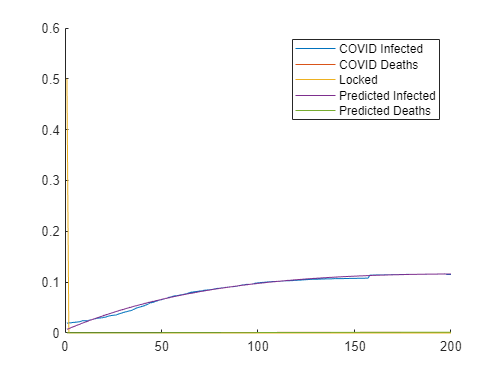


recovered = zeros(size(y(:,3)));
% Assuming COVID takes 7 days to kill / recover, according to CDC

for i=9:length(recovered)
    recovered(i) = coviddata(i-7,1)-coviddata(i-8,1) - (coviddata(i-7,2)-coviddata(i-8,2));
end
recovered = cumsum(recovered);

% create figure
figure;
% hold on to plot data
hold on;
plot(coviddata)
plot(y(:,2))
plot(y(:,3))
plot(y(:,5))
% legend
legend('COVID Infected','COVID Deaths','Locked','Predicted Infected','Predicted Deaths');
hold off

 
% plot(Y);
% legend('S','L','I','R','D');
% xlabel('Time')

% Y_fit = siroutput_full(x,t);
% 
% figure(1);

% Make some plots that illustrate your findings.
% TO ADD
